## AAE440 HW8 PROBLEM 1 MATLAB

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE440\MATLAB\outputs\HW8';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

% Arrow drawing function
drawArrow = @(x,y,varargin) quiver( x(1),y(1),x(2)-x(1),y(2)-y(1),0, varargin{:} );

#### (a)

% Given properties
I_body = [400 0 0; 0 100 0; 0 0 400];  % [kg-m2]
I = I_body(1,1); J = I_body(2,2);
w_NU_mag = 4;  % magnitude of angular velocity [rad/s]
w_NU_hat = [0 cosd(60) sind(60)];  % angle of w_NU relative to u_2 [deg]
w_NU = w_NU_mag*w_NU_hat;

% Kinetic rotational energy 
Trot = 0.5*w_NU*I_body*w_NU.'

Trot = 2600

% Semi-diameters of energy ellipsoid
d1 = sqrt(2*Trot*I^(-1))

d1 = 3.6056

d2 = sqrt(2*Trot*J^(-1))

d2 = 7.2111

d3 = d1

d3 = 3.6056

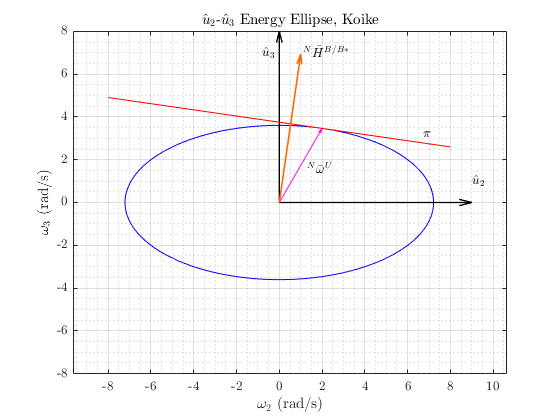

% Plotting the inertial ellipsoid
theta = 0:0.01:2*pi;
u_str = ["$\hat{u}_1$","$\hat{u}_2$","$\hat{u}_3$"];

% u2-u3
fig1 = figure("Renderer","painters");
    plot(d2*cos(theta), d3*sin(theta), 'b')
    title('$\hat{u}_2$-$\hat{u}_3$ Energy Ellipse, Koike')
    xlabel('$\omega_2$ (rad/s)')
    ylabel('$\omega_3$ (rad/s)')
    hold on 
    drawArrow([0 9], [0 0],'k','linewidth',1); text(9,1,u_str(2),"Interpreter","Latex");
    drawArrow([0 0], [0 8],'k','linewidth',1); text(-0.8,7,u_str(3),"Interpreter","Latex");
    
    % Angular velocity
    drawArrow([0 w_NU(2)], [0 w_NU(3)],'color','#FD07EA'); 
    text(1.3,1.5,'${}^N\bar{\omega}^U$','Interpreter','Latex');
    
    % Invariable plane PI
    [a, b] = line_tangent2ellipse(w_NU(2),w_NU(3),d2,d3);
    x = -8:0.1:8;
    y = a*x + b;
    plot(x,y,'-r'); text(6.7,3.2,'$\pi$','Interpreter',"latex");
    
    % H_body
    drawArrow([0 1.0],[0 1.0*(-1/a)],'color','#FF6800','linewidth',1.2)
    text(1.1,7,'${}^N\bar{H}^{B/B*}$')
    
    hold off
    xlim([-9 9]); ylim([-8 8]);
    grid on; grid minor; box on; axis equal;
saveas(fig1, fullfile(fdir,'P1-a-u2_u3_EN-ellipse.png'));

### (b)

% Angular momentum 
H_NU = I_body*w_NU.'

H_NU = 	1.0e+03 *

         0
    0.2000
    1.3856


H_NU_mag = norm(H_NU)

H_NU_mag = 1400


% Computing p, s, and phi
p = H_NU_mag/I;
s = (I - J)/I*w_NU(2);
phi = acos(H_NU(2)/H_NU_mag)

phi = 1.4274

phi_deg = rad2deg(phi)

phi_deg = 81.7868


% Computing the precession, nutation, and spin angles 
% @ t = 0.25
t = 0.25;
sigma = p*t

sigma = 0.8750

sigma_deg = rad2deg(sigma)

sigma_deg = 50.1338

eta = s*t

eta = 0.3750

eta_deg = rad2deg(eta)

eta_deg = 21.4859


% @ t = 3.5
t = 3.5;
sigma = mod(p*t,2*pi)

sigma = 5.9668

sigma_deg = rad2deg(sigma)

sigma_deg = 341.8733

eta = mod(s*t,2*pi)

eta = 5.2500

eta_deg = rad2deg(eta)

eta_deg = 300.8028

h_hat_U = H_NU/H_NU_mag;
h_hat_C = [0 cos(phi) -sin(phi)];
% gamma
syms t1
e_NC = h_hat_C*sin(p*t1/2);  
e4_NC = cos(p*t1/2);

% DCM
% @ t= 0.25
e_NC_025 = double(subs(e_NC,t1,0.25));
e4_NC_025 = double(subs(e4_NC,t1,0.25));
C_NC_025 = DCM_from_EulerPara([e_NC_025 e4_NC_025])

C_NC_025 =     0.6410    0.7597    0.1096
   -0.7597    0.6483   -0.0508
   -0.1096   -0.0508    0.9927


% @ t= 3.5
e_NC_35 = double(subs(e_NC,t1,3.5));
e4_NC_35 = double(subs(e4_NC,t1,3.5));
C_NC_35 = DCM_from_EulerPara([e_NC_35 e4_NC_35])

C_NC_35 =     0.9504   -0.3079   -0.0444
    0.3079    0.9514   -0.0070
    0.0444   -0.0070    0.9990



gamma_025 = acosd(C_NC_025(2,2))

gamma_025 = 49.5847

gamma_35 = acosd(C_NC_35(2,2))

gamma_35 = 17.9392

### (c)

% Euler parameters 
c2_hat = [0 1 0];
syms t
e_NC = h_hat_C*sin(p*t/2);  
e4_NC = cos(p*t/2);
e_CU = c2_hat*sin(s*t/2);
e4_CU = cos(s*t/2);

e_NU = e_NC*e4_CU + e_CU*e4_NC + cross(e_CU,e_NC);
e4_NU = e4_NC*e4_CU - dot(e_NC,e_CU);

% C-frame
% @ t = 0.25
e_NU_025_C = double(subs(e_NU,t,0.25))

e_NU_025_C =    -0.0782    0.2283   -0.4120


e4_NU_025 = double(subs(e4_NU,t,0.25))

e4_NU_025 = 0.8787


% @ t = 3.5
e_NU_35_C = double(subs(e_NU,t,3.5))

e_NU_35_C =     0.0770    0.5073   -0.1356


e4_NU_35 = double(subs(e4_NU,t,3.5)) 

e4_NU_35 = -0.8475

% U-frame
syms t2
C_CU = [cos(s*t2) 0 -sin(s*t2); 
                0 1          0;
        sin(s*t2) 0  cos(s*t2)];
% @ t = 0.25
e_NU_025_U = double(e_NU_025_C*subs(C_CU,t2,0.25))

e_NU_025_U =    -0.2236    0.2283   -0.3547


C_NU_025_1 = double(C_NC_025*subs(C_CU,t2,0.25))

C_NU_025_1 =     0.6366    0.7597   -0.1328
   -0.7255    0.6483    0.2310
    0.2616   -0.0508    0.9639


C_NU_025_2C = DCM_from_EulerPara([e_NU_025_C e4_NU_025])

C_NU_025_2C =     0.5563    0.6883    0.4656
   -0.7597    0.6483   -0.0508
   -0.3368   -0.3255    0.8835


C_NU_025_2U = DCM_from_EulerPara([e_NU_025_U e4_NU_025])

C_NU_025_2U =     0.6441    0.5212    0.5599
   -0.7255    0.6483    0.2310
   -0.2426   -0.5550    0.7957



% @ t = 3.5
e_NU_35_U = double(e_NU_35_C*subs(C_CU,t2,3.5))

e_NU_35_U =     0.1559    0.5073   -0.0033


### (d)

gamma_max = 2*phi_deg;

### (e)

alpha = 2*(phi_deg - 60)

alpha = 43.5736

### ADDITIONAL (FOR PROBLEM 2)

tspan = 0:0.005:15;
fig2 = figure("Renderer","painters")

fig2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


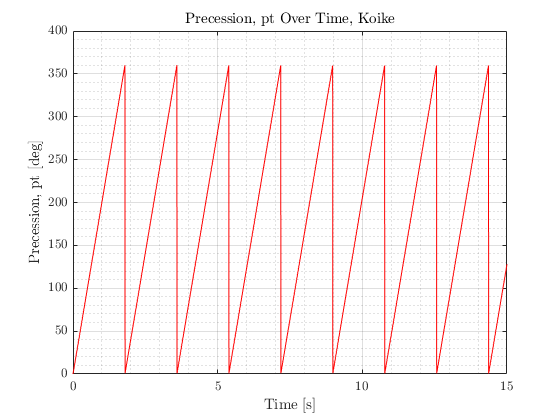

    plot(tspan,rad2deg(mod(p*tspan,2*pi)),'r')
    title("Precession, pt Over Time, Koike")
    ylabel('Precession, pt [deg]')
    xlabel('Time [s]')
    grid on; grid minor; box on;
saveas(fig2,fullfile(fdir,"pt_precession.png"))


fig3 = figure("Renderer","painters")

fig3 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


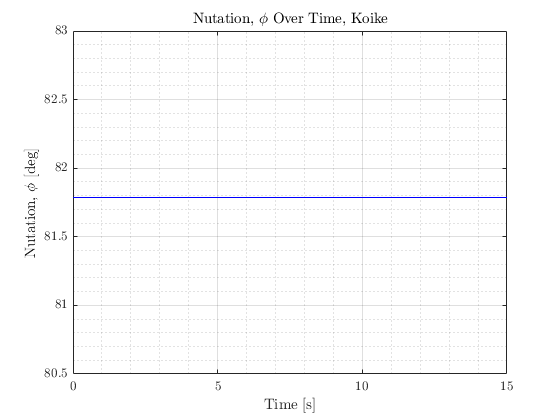

    plot(tspan,rad2deg(phi).*ones(size(tspan)),'b')
    title("Nutation, $\phi$ Over Time, Koike")
    ylabel('Nutation, $\phi$ [deg]')
    xlabel('Time [s]')
    grid on; grid minor; box on;
saveas(fig3,fullfile(fdir,"phi_nutation.png"))

% gamma 
tspan = 0:0.005:15;
gamma_new = zeros(size(tspan));
ct = 1;
for t = tspan
    e_NC_new = h_hat_C*sin(p*t/2);  
    e4_NC_new    = cos(p*t/2);
    C_NC_new = DCM_from_EulerPara([e_NC_new e4_NC_new]);
    gamma_new(ct) = acosd(C_NC_new(2,2));
    ct = ct + 1;
end

fig4 = figure("Renderer","painters")

fig4 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


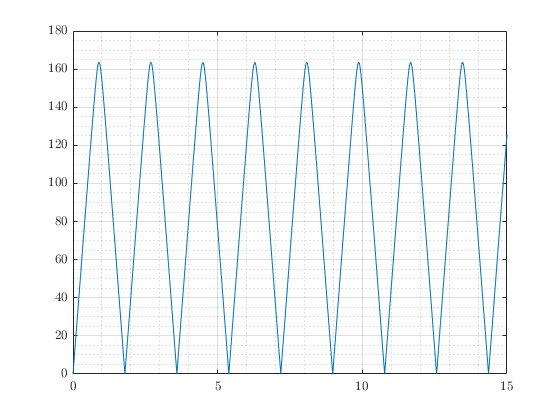

    plot(tspan,gamma_new)
    grid on; grid minor; box on;

### FUNCTION

function [slope, y_intercept] = line_tangent2ellipse(x1,y1,a,b)
    slope = -x1/y1*b^2/a^2;
    y_intercept = y1 - x1*slope;
end